# Load data

clear
load('Assignment_Data_SC42145.mat');
load('Q2_syn.mat'); 
K = minreal(K);

22 states removed.


G = tf(FWT(1:2,1:2));


## Build Matrices


% build Performance Weight matrices
Wp11 = tf([1/1.8, 0.8*pi], [1, 0.8*pi*1e-4]);
Wu22 = tf([5e-3, 7e-4, 5e-5], [1, 14e-4, 1e-6]);

Wp = [Wp11 0; 0 0.2];
Wu = [0.01 0; 0 Wu22];

% build Uncertainty Weight matrices
Wi1 = tf([1/(16*pi), 0.3], [1/(64*pi), 1]);
Wi2 = Wi1;
Wo1 = tf([0.05, 0.2], [0.01, 1]);
Wo2 = Wo1;

Wi = [Wi1 0; 0 Wi2];
Wo = [Wo1 0; 0 Wo2];

% Build Delta Block
D1 = ultidyn('Din1', [1,1], 'Bound', 1);
D2 = ultidyn('Din2', [1,1], 'Bound', 1); 
D3 = ultidyn('Dout1', [1,1], 'Bound', 1); 
D4 = ultidyn('Dout2', [1,1], 'Bound', 1);
Din = [D1 0; 0 D2];
Dout = [D3 0; 0 D4];
Delta = [Din zeros(2,2); zeros(2,2) Dout];

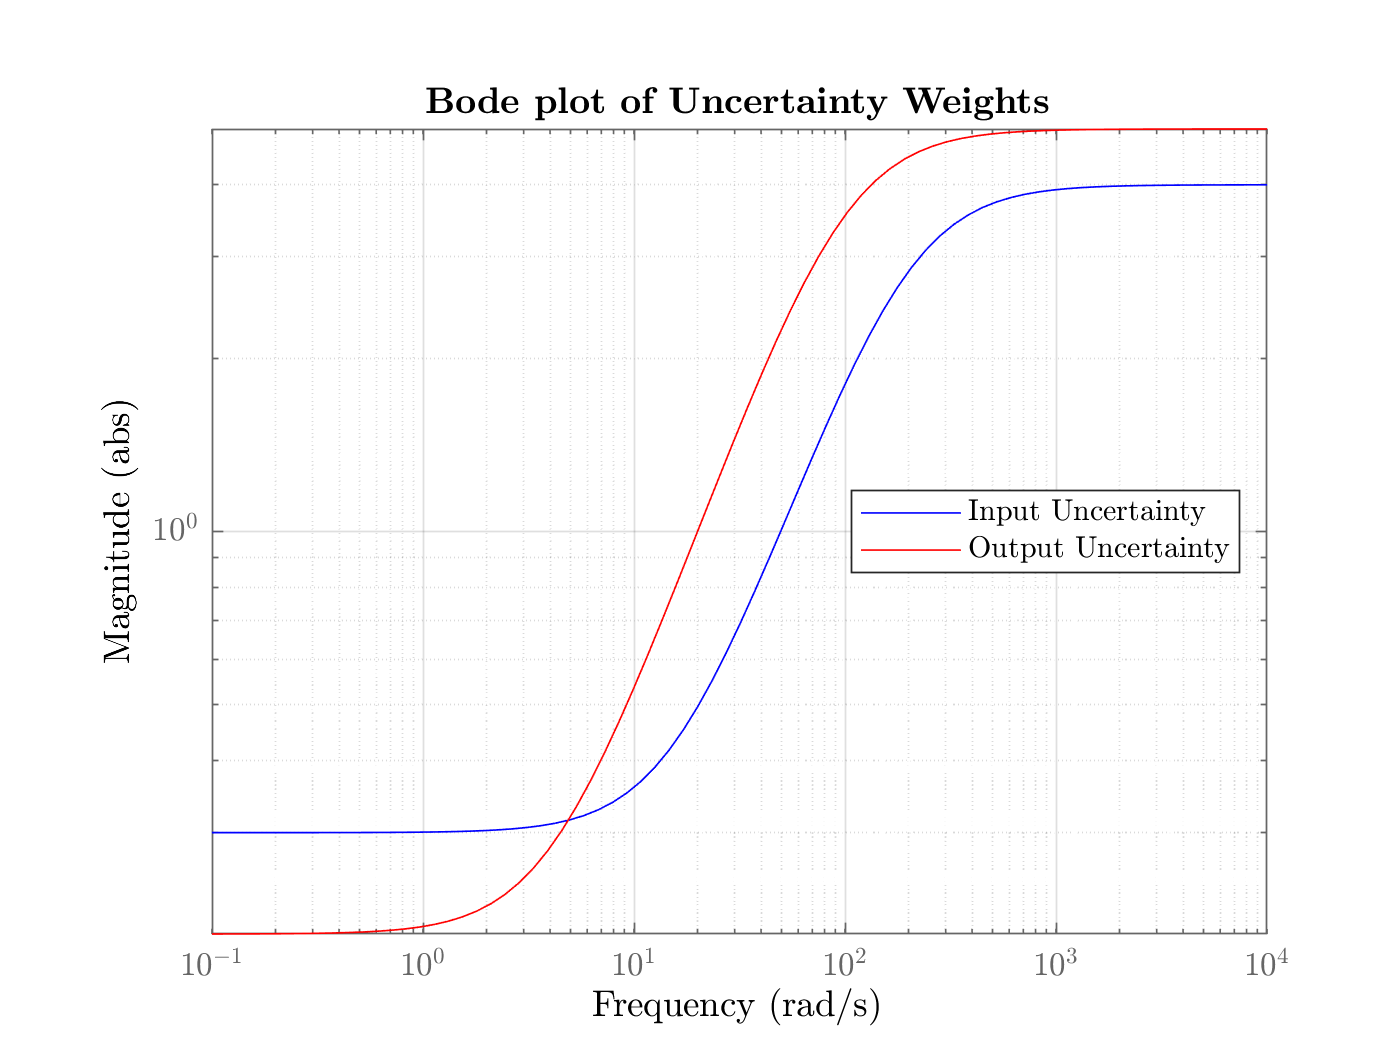

% plot weights
figure();
bodemag(Wi1, 'blue'); hold on;
latex_bodemag(Wo1, 'Uncertainty Weights', 'red');
legend('Input Uncertainty', 'Output Uncertainty', 'interpreter', 'latex', 'Location', 'east');
saveas(gcf, 'Figures/ch4_uncertainty_weights.eps',  'epsc')


% plot uncertain weights
figure();


## Generalized Plant

P11 = [zeros(2,4); Wo*G zeros(2,2)];
P12 = [zeros(2,2) Wi; zeros(2,2) Wo*G];
P21 = [Wp*G Wp; zeros(2, 4)];
P22 = [Wp Wp*G; zeros(2,2) Wu];
P31 = [-G -1*eye(2)];
P32 = [-1*eye(2) -G];

P = [P11 P12; P21 P22; P31 P32];
N = lft(P,K);
M = lft(Delta, N);
